## **Proyecto 3 - Procesamiento de Señales**

**Juan Nicolás Quintero - Ana María Garzón - Juan Manuel Dávila**

El objetivo principal de este microproyecto 3 es diseñar y construir un algoritmo que utilice la FFT para enviar información de color en una foto a color; buscando pasar de una imagen a una señal para la cual se obtienen los coeficientes de Fourier y así seleccionar los coeficientes con base en un error. Estos coeficientes podrán luego ser enviados a través de un canal de comunicación. 

**Aplicación seleccionada: **Clasificación de naranjas

**Base de datos con las imagenes: **[https://github.com/anamarigarzon/Proyecto-Procesamiento-de-Senales/tree/main/imagenes](https://github.com/anamarigarzon/Proyecto-Procesamiento-de-Senales/tree/main/imagenes)

Para comenzar, usaremos una de las imagenes de la base de datos y la visualizaremos

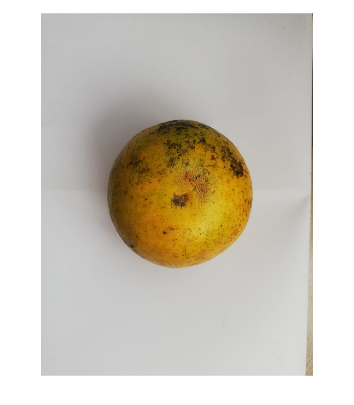

% lectura de imagen "amarillas\Natural\amarilla_luz_natural_no_flash_frente.jpeg"
% No olvidar editar ruta de imagen
I = imread("C:\Users\garzo\Downloads\Proyecto Procesamiento de Señales\amarillas\Natural\amarilla_luz_natural_no_flash_abajo.jpeg");
imshow(I) % visualización de la imagen

A continuación, distinguiremos la región de interés (naranja) del resto de la imagen

size(I);
e1 = [I(1,1,1) I(1,1,2) I(1,1,3)];
e2 = [I(1,size(I, 2),1) I(1,size(I, 2),2) I(1,size(I, 2),3)];
e3 = [I(size(I,1),1,1) I(size(I,1),1,2) I(size(I,1),1,3)];
e4 = [I(size(I,1),size(I,2),1) I(size(I,1),size(I,2),2) I(size(I,1),size(I,2),3)];

E = [e1;e2;e3;e4];
avg = mean(E,1) -50;

for i=1:1:size(I,1)
    for j=1:1:size(I,2)
        if I(i,j,1) > avg(1)
            if I(i,j,2) > avg(2)
                if I(i,j,3) > avg(3)
                    I(i,j,1) = 0;
                    I(i,j,2) = 0;
                    I(i,j,3) = 0;
                end
            end
        end
    end
end

imshow(I);

Ahora, visualizaremos la imagen con un mapa de calor por cada uno de los componentes RGB.

Comenzaremos con el rojo

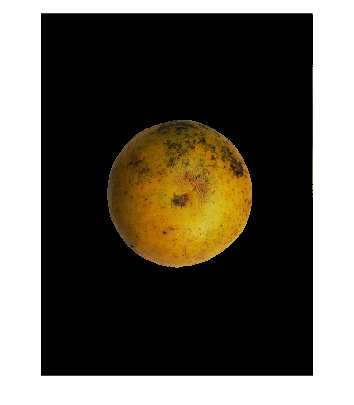

rojo = I(:,:,1);
mapajet = colormap(jet(256));

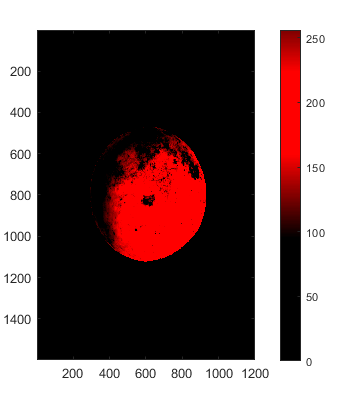

mapaRnuevo=[mapajet(:,1), zeros(256,1), zeros(256,1)];
image(rojo), colormap(mapaRnuevo), colorbar;

Ahora visualizaremos las componentes en verde

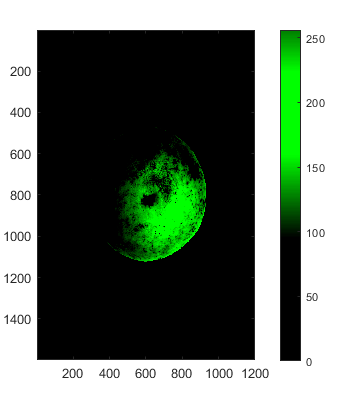

verde = I(:,:,2);
mapaVnuevo=[zeros(256,1), mapajet(:,1), zeros(256,1)];
image(verde), colormap(mapaVnuevo), colorbar;

Finalmente, los componentes en azul

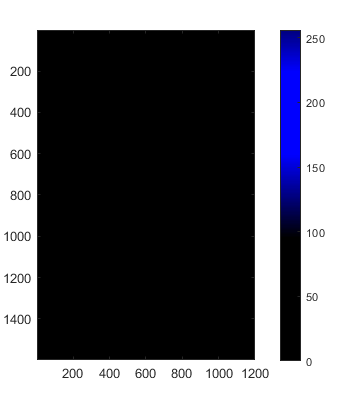

azul = I(:,:,3);
mapaAnuevo=[zeros(256,1), zeros(256,1),  mapajet(:,1)];
image(azul), colormap(mapaAnuevo), colorbar;

Para hacernos una idea de como está compuesta la imagen, podemos obtener la media de cada color, para la región de interés.

comp_rojo = [];
comp_verde = [];
comp_azul = [];

for i=1:1:size(I,1)
    for j=1:1:size(I,2)
        if I(i,j,1) > 0 && I(i,j,2) > 0 && I(i,j,3) > 0
                    comp_rojo = [comp_rojo, I(i,j,1)];
                    comp_verde = [comp_verde, I(i,j,2)];
                    comp_azul = [comp_azul, I(i,j,3)];
        end
    end
end

%media para la componente en rojo
media_rojo = mean(comp_rojo)

media_rojo = 149.5882

%media para la componente en verde
media_verde = mean(comp_verde)

media_verde = 106.6037

%media para la componente en azul
media_azul = mean(comp_azul)

media_azul = 18.5786

Lo que haremos ahora será crear un vector que tendrá primero las entradas de las componentes en rojo, luego las del verde y finalmente las del azul. Este vector será el que introduciremos en el algoritmo FFT.  La señal tendrá tres intervalos cada uno con los valores RGB extraídos de la región de interés y con 1024 muestras, para tener un vector final con 3092 muestras

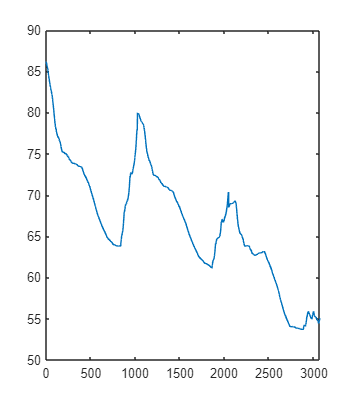

[a,b] = size(comp_rojo);
tamano_intervalo = floor(b/1024);
comp_rojo_1024 = [];
comp_verde_1024 = [];
comp_azul_1024 = [];

for i=1:1:1024
    comp_rojo_1024 = [comp_rojo_1024, mean(comp_rojo(i:i+(tamano_intervalo-1)))];
    comp_verde_1024 = [comp_verde_1024, mean(comp_verde(i:i+(tamano_intervalo-1)))];
    comp_azul_1024 = [comp_azul_1024, mean(comp_azul(i:i+(tamano_intervalo-1)))];
end

vector_rgb = [comp_rojo_1024,comp_verde_1024,comp_azul_1024];
plot(vector_rgb)

Aplicaremos el algoritmo FFT al vector

% Aplicación del algorimo FFT
fourier = fft(vector_rgb);

El número de componentes de frecuencia que se pueden obtener es:

A continuación construiremos el eje de la frecuencia para visualizar la FFT

% Creación del eje de frecuencia
% Visualización de la FFT

El número de componentes de frecuencia (coeficientes) para que el error se encuentre entre 5% y el 10% es de

% EN REALIDAD NO TENGO NI IDEA DE QUÉ HAY QUÉ HACER AQUI, AIUDA

Reconstrucción con la IFFT de la señal con las componentes que cumplen con el error seleccionado.

% Recontrucción con IFFT

Este procedimiento se lleva a cabo con cada una de las imagenes de la base de datos y se ha creado un archivo *.mat por cada señal. El nombre del archivo continene información sobre si la naranja es amarilla o verde, y las condiciones de iluminación de la imagen.

Finalmente, tomamos no de los conjuntos de coeficientes de señales de otro grupo y reconstruimos la señal.

% Cargar conjunto de señales de otro grupo
% Reconstrucción de la señal